function mat = genSymMatrix(N, condnumber, lambda, filename)
file = fopen(filename, "w");

T = diag(linspace(1, condnumber, N));
[Q, R] = qr(rand(N));
mat = Q*T*Q';

fwrite(file, N, "int32");
fwrite(file, lambda, "double");
fwrite(file, mat, "double");

fclose(file);
end

conds = [
    (1/0.6 - 1)*0.5*10, 
    (1/0.5 - 1)*0.5*10, 
    (1/0.4 - 1)*0.5*10, 
    (1/0.3 - 1)*0.5*10, 
    (1/0.2 - 1)*0.5*10, 
    (1/0.1 - 1)*0.5*10
]

conds =     3.3333
    5.0000
    7.5000
   11.6667
   20.0000
   45.0000


d1 = [0.50 0.50 0.50 0.50 0.50 0.50]

d1 =     0.5000    0.5000    0.5000    0.5000    0.5000    0.5000


d2 = conds/10 + 0.50

d2 =     0.8333
    1.0000
    1.2500
    1.6667
    2.5000
    5.0000



razdel = d1' ./ d2

razdel =     0.6000
    0.5000
    0.4000
    0.3000
    0.2000
    0.1000


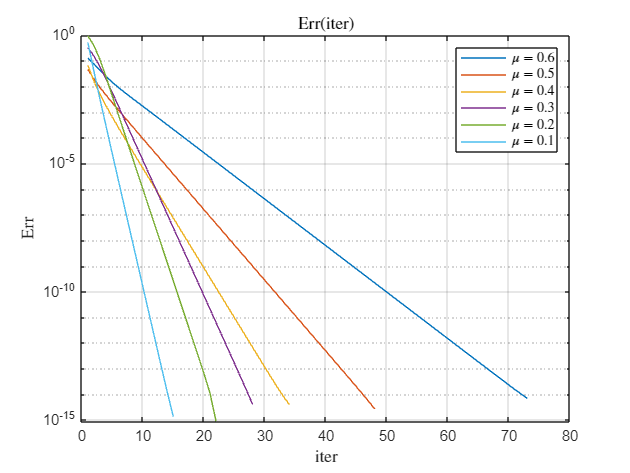

% ms = cell(numel(conds), 1);
% 
% for c = 1:numel(conds)
%     m = genSymMatrix(10, conds(c), 0.50, ...
%         sprintf("iim_cond%i_SRC.bin", c));
%     ms{c} = m;
% end



figure


for c = 1:numel(conds)
    T = readtable(sprintf("iim_cond%i_RES.csv", c));
    dLam = abs(T{1:end, 2} - 1);

    semilogy(T{1:end, 1}, dLam);
    hold on
end
grid on
legend("$\mu = 0.6$", "$\mu = 0.5$", "$\mu = 0.4$", "$\mu = 0.3$", "$\mu = 0.2$", "$\mu = 0.1$", Interpreter="latex")
title("Err(iter)", Interpreter="latex")
xlabel("iter", Interpreter="latex")
ylabel("Err", Interpreter="latex")

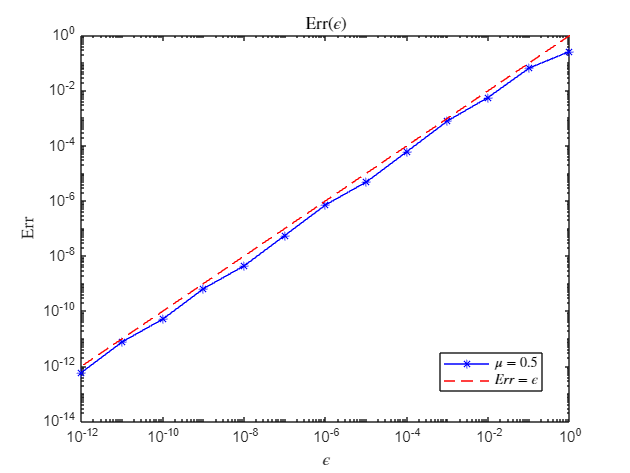

figure
T1 = readtable("iim_cond2_CONV_RES.csv");
T2 = readtable("iim_cond1_CONV_RES.csv");
dl1 = abs(T1{1:end, 2} - 1);
dl2 = abs(T2{1:end, 2} - 1);

loglog(T1{1:end, 1}, dl1, "b*-")
hold on
%loglog(T2{1:end, 1}, dl2, "g*-")

loglog(T1{1:end, 1}, T1{1:end, 1}, "r--")
xlabel("$\epsilon$", Interpreter="latex")
ylabel("Err", Interpreter="latex")
title("Err($\epsilon$)", Interpreter="latex");
legend("$\mu = 0.5$", "$Err = \epsilon$", Interpreter="latex")

legend(["$\mu = 0.5$", "$Err = \epsilon$"], "Interpreter", "latex", "Position", [0.6990 0.1753 0.1613, 0.0792])

L = [1 0; 0.769 1];
U = [1.3 1; 0 0.531];
A = [2 1; 1 2];

x1 = L\[1; -0.769]

x1 =     1.0000
   -1.5380


x1 = U\x1 / 1.8832

x1 =     1.5916
   -1.5380


norm(x1)

ans = 2.2133

A*x1

ans =     1.6451
   -1.4845


norm(A*x1 - x1)

ans = 0.0757

0.727 / 2.376

ans = 0.3060